clear

Read in AC Load (from Menzies Building)

data = readtable("dataCleaned.csv");

data = renamevars(data, "ptot","AC");      %Rename the AC electrical load to AC
summary(data)

Variables:

    tstamp: 8760×1 datetime

        Properties:
            Description:  tstamp
        Values:

            Min       01-Jan-2022 00:00:00
            Median    02-Jul-2022 11:30:00
            Max       31-Dec-2022 23:00:00

    date: 8760×1 double

        Properties:
            Description:  date
        Values:

            Min           1   
            Median      183   
            Max         365   

    day: 8760×1 double

        Properties:
            Description:  day
        Values:

            Min          1    
            Median       4    
            Max          7    

    time: 8760×1 double

        Properties:
            Description:  time
        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    week_number: 8760×1 double

        Properties:
            Description:  week_number
        Values:

        

%Removing date (have tstamp),
% Removing time(have working hours and daytime)
%Removing day (have Weekday, Sat, Sun)

data = removevars(data,["tstamp","week_number","epoch_timestamp","month"]);


data = data(:, ["AC", "time", "DC", "date", "day", "wrkHr","dayTime","Off_Peak","Peak","Standard","weekDay"])

data = 8760×11 table
      AC        time       DC     date    day    wrkHr    dayTime    Off_Peak    Peak    Standard    weekDay
    ______    ________    ____    ____    ___    _____    _______    ________    ____    ________    _______

    96.855           0    52.2     1       6       0         0          1         0         0           0   
    97.053    0.041667      52     1       6       0         0          1         0         0           0   
    97.229    0.083333    52.2     1       6       0         0          1         0         0           0   
    96.859       0.125    52.2     1       6       0       

summary(data)

Variables:

    AC: 8760×1 double

        Properties:
            Description:  ptot
        Values:

            Min         79.12 
            Median     165.23 
            Max        304.46 

    time: 8760×1 double

        Properties:
            Description:  time
        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    DC: 8760×1 double

        Properties:
            Description:  DC
        Values:

            Min         35.6  
            Median      70.7  
            Max        211.7  

    date: 8760×1 double

        Properties:
            Description:  date
        Values:

            Min           1   
            Median      183   
            Max         365   

    day: 8760×1 double

        Properties:
            Description:  day
        Values:

            Min          1    
            Median       4    
        

**Train model**

%Need to get rid of date time. Think Imma keep Hour

labels = data.Properties.VariableNames;

%data=normalize(data(:,["AC","DC", "day", "time"] ));

% minAC = min(data.AC(:))
% minDC = min(data.DC(:))
% minDay = min(data.day(:));
% minTime = min(data.time(:));
% 
% maxAC = max(data.AC(:))
% maxDC = max(data.DC(:))
% maxDay = max(data.day(:));
% maxTime = max(data.time(:));
% 
% data.AC = (data.AC(:) - minAC)/(maxAC-minAC);
% data.DC = (data.DC(:) -minDC)/(maxDC - minDC);
% data.day = (data.day(:) - minDay)/(maxDay - minDay);
% data.time = (data.time(:) -minTime)/(maxTime - minTime);

summary(data)

Variables:

    AC: 8760×1 double

        Properties:
            Description:  ptot
        Values:

            Min         79.12 
            Median     165.23 
            Max        304.46 

    time: 8760×1 double

        Properties:
            Description:  time
        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    DC: 8760×1 double

        Properties:
            Description:  DC
        Values:

            Min         35.6  
            Median      70.7  
            Max        211.7  

    date: 8760×1 double

        Properties:
            Description:  date
        Values:

            Min           1   
            Median      183   
            Max         365   

    day: 8760×1 double

        Properties:
            Description:  day
        Values:

            Min          1    
            Median       4    
        

For lstm I want to break the time series up into shorter batches

Batch size 7days. 

Create cell array with a cell for each batch

Each batch is 7days of observations (rows are variables and columns are time steps)

numDays = 35;

height = ceil(size(data(:,1))/(numDays*24));
dataCell = cell(height(1), 1);

for i = 1:numel(dataCell)
    %Get the range of rows that you need for this batch
    startIdx = (i-1)*numDays*24 + 1;
    endIdx   = min(i*numDays*24, size(data(:,1)));
    %Store the batch in an array
    currentBatch = table2array(data(startIdx:endIdx, :));
    %transpose array so that columns are timesteps
    currentBatch = transpose(currentBatch);
    %Store in cell array
    dataCell{i} = currentBatch;
end


Split data for Training and testing

numObservations = numel(dataCell);
perctSplit = 0.7

perctSplit = 0.7000


idxTrain = 1:floor(perctSplit*numObservations);
idxTest = floor(perctSplit*numObservations)+1:numObservations;
dataTrain = dataCell(idxTrain);
dataTest = dataCell(idxTest);

To forecast the values of future time steps of a sequence, specify the targets as the training sequences with values shifted by one time step. In other words, at each time step of the input sequence, the LSTM neural network learns to predict the value of the next time step. The predictors are the training sequences without the final time step.

**NOTE Try to change TTrain to only hold the future values of AC and DC since those are the values I am interested in?**

for n = 1:numel(dataTrain)
    %select batches one at a time.
    X = dataTrain{n}; 
    %Set the full sequence minus the last value as the predictors 
    XTrain{n} = X(:,1:end-1);
    %Set the Sequence but one step forward as the targets
    TTrain{n} = X(:,2:end);
end 

%Do the same for the test data
for n  = 1:numel(dataTest);
    X = dataTest{n};
    XTest{n} = X(:,1:end-1);
    TTest{n} = X(:,2:end);
end

We need to normailse the data to have a zero mean and unit variance. 

Note, Use the same mean and std deviation that you calculated on the training data on the test data. 

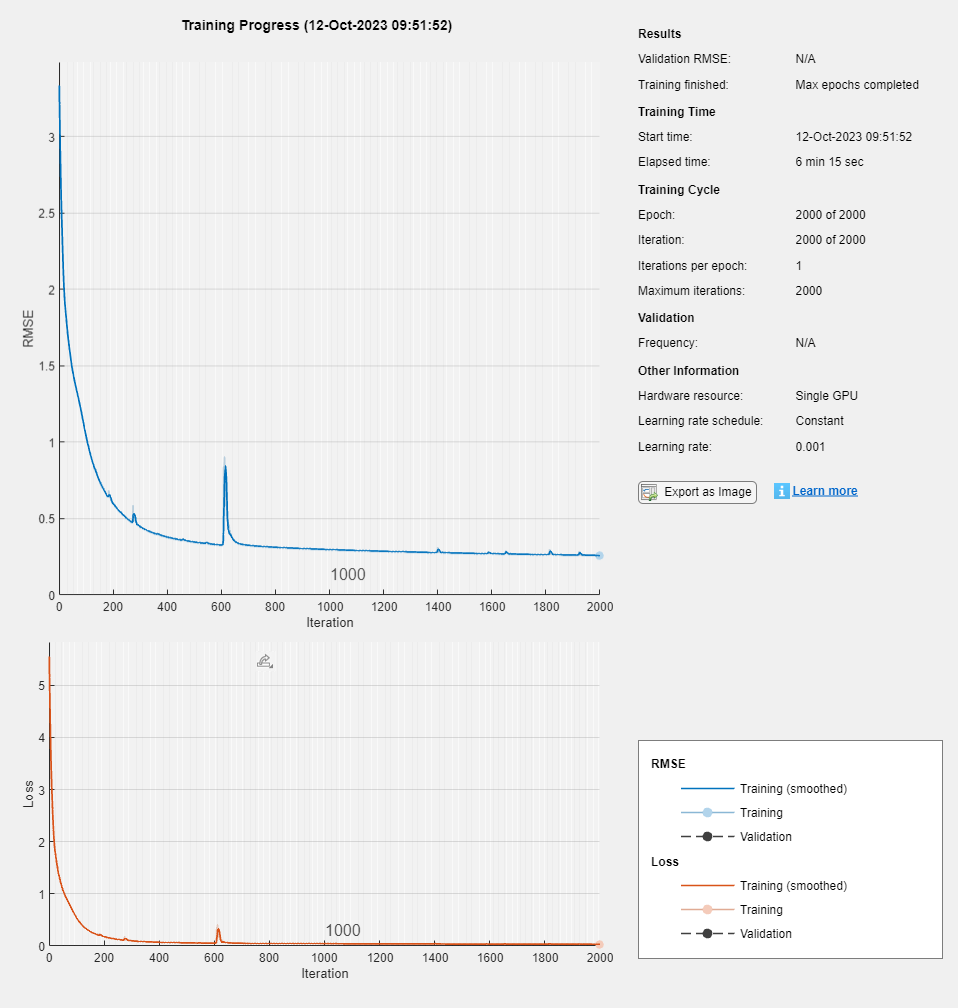

%Mean of training 
meanX = mean(cat(2,XTrain{:}),2);
sigmaX = std(cat(2,XTrain{:}),0,2);
%Mean of training Targets
meanT = mean(cat(2,TTrain{:}),2);
sigmaT = std(cat(2,TTrain{:}),0,2);

%apply to the training data
for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n}-meanX)./sigmaX;
    TTrain{n} = (TTrain{n}-meanT)./sigmaT;
end
%apply to the test data
for n = 1:numel(XTest)
    XTest{n} = (XTest{n}-meanX)./sigmaX;
    %TTest{n} = (TTest{n}-meanT)./sigmaT;
end

numChannels = size(dataCell{1},1); 

layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)
    regressionLayer];


options = trainingOptions("adam", ...
    MaxEpochs=2000, ...
    SequencePaddingDirection="left", ...    
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(XTrain,TTrain,layers,options);

**Test Network **

using the Test data and the trained net to make predictions.

preds = predict(net, XTest, SequencePaddingDirection="left");

Undo the standardisation on the predictions

for n = 1:numel(preds)
    preds{n} = (preds{n}.*sigmaT)+meanT;
end

To test the RMSE

for i = 1:size(preds,1)
    for k = 1:size(preds{1}(:,1))
        rmse(i,k) = sqrt(mean((preds{i}(k,:) - TTest{i}(k,:)).^2,"all"));
        mape(i,k) =   mean(abs((TTest{i}(k,:)-preds{i}(k,:))./TTest{i}(k,:)),"all")*100;
    end
end

for idxBatch = 1:numel(XTest)

figure
plot(TTest{idxBatch}(1,:));
hold on
plot(preds{idxBatch}(1,:));
hold off
legend("Actual AC", "Predictions AC");
title("AC prediction testBatch: " + idxBatch)

figure
plot(TTest{idxBatch}(3,:));
hold on
plot(preds{idxBatch}(3,:));
hold off
legend("Actual DC", "Predictions DC");
title("DC prediction test Batch: " + idxBatch)

end


figure
subplot(1,3,1)
histogram(mape(:,1))
title("AC MAPE " + mean(mape(:,1)) +"%" )
subplot(1,3,2)
plot(mape(:,1))
subplot(1,3,3)
bar(mape(:,1))

figure

subplot(1,3,1)
histogram(rmse(:,1))
title("AC RMSE" + mean(rmse(:,1)))
subplot(1,3,2)
plot(rmse(:,1))
subplot(1,3,3)
bar(rmse(:,1))



figure
subplot(1,3,1)
histogram(mape(:,3))
title("DC MAPE " + mean(mape(:,3)) +"%" )
subplot(1,3,2)
plot(mape(:,3))
subplot(1,3,3)
bar(mape(:,3))


figure
subplot(1,3,1)
histogram(rmse(:,3))
title("DC RMSE" + mean(rmse(:,3)))
subplot(1,3,2)
plot(rmse(:,3))
subplot(1,3,3)
bar(rmse(:,3))

**Closed loop forcasting to predict full day ahead :)**

Predict values **t ** through to **t+k ** when you have data collected for steps **1 ** through to **t-1;**

timeStep = 1;
numel(XTest)

ans = 4

idx=1;
X = [];
T=  [];
for i = 1:(numel(XTest))
    X = [X (XTest{i}(:,:))];
    T = [T (TTest{i}(:,:))];
end
   for j = 1:(floor(length(X(1,:))/timeStep)-ceil(24/timeStep))
        net = resetState(net);
        offset =  j*timeStep+1;
        [net,Z] = predictAndUpdateState(net,X(:,1:offset));
        
        numPredictionTimeSteps = 24;
        Xt = Z(:,offset);
        Y = zeros(numChannels, numPredictionTimeSteps); % the 2 is for the 2 output channels
        
        for t = 1:numPredictionTimeSteps
            [net,Y(:,t)] = predictAndUpdateState(net,Xt);
            Xt = Y(:,t);
        end
        
        %Undo Normalisation
        Y = (Y.*sigmaT)+meanT;
        numTimeSteps = offset+numPredictionTimeSteps-1;
        % 
        % figure
        % t=tiledlayout(2,1);
        % title(t, "Day ahead forecasting for Electrical load. BATCH NO: " + idx + " OFFSET: " +offset)
        % 
        % nexttile 
        % plot(T(1,1:offset))
        % hold on 
        % plot(offset:numTimeSteps,[T(1,offset) Y(1,:)],'--') 
        % plot( offset:numTimeSteps, T(1,offset:numTimeSteps),'r')
        % ylabel("AC day ahead forcast")
        % legend("Input","24h Forecast","24hr Actual","Location","northwest")
        % 
        % nexttile 
        % plot(T(3,1:offset))
        % hold on 
        % plot(offset:numTimeSteps,[T(3,offset) Y(3,:)],'--')
        % plot(offset:numTimeSteps, T(3,offset:numTimeSteps),'r')
        % ylabel("DC day ahead forcast")
        % legend("Input","24hr Forecast","24hr Actual","Location","northwest")

 

        for i = 1:size(Y(:,1))
                rmse(j,i) = mean((Y(i,:) - T(i,offset:numTimeSteps)).^2,"all");
                mape(j,i) =   mean(abs(T(i,offset:numTimeSteps)-Y(i,:))./T(i,offset:numTimeSteps),"all")*100;
        end

        for i = 1:size(Y(:,1))
                rmsePerHr(j,i,:) = (Y(i,:) - T(i,offset:numTimeSteps)).^2;
                mapePerHr(j,i,:) =   abs(T(i,offset:numTimeSteps)-Y(i,:))./T(i,offset:numTimeSteps)*100;
        end
       
   end



 
   net = resetState(net);
   offset =  96;
   [net,Z] = predictAndUpdateState(net,X(:,1:offset));

   numPredictionTimeSteps = 24;
   numTimeSteps = offset+numPredictionTimeSteps-1;
   Xt = Z(:,offset);
   Y = zeros(numChannels, numPredictionTimeSteps); % the 2 is for the 2 output channels
   for t = 1:numPredictionTimeSteps
       [net,Y(:,t)] = predictAndUpdateState(net,Xt);
       Xt = Y(:,t);
   end
       
   testAct = T(1, offset:numTimeSteps)

testAct =   114.0870  115.4010  114.2740  114.8920  115.4270  116.4150  199.0230  243.2800  269.0160  289.3150  293.3540  301.8220  287.7460  291.0200  286.8940  286.6150  268.0800  250.7890  240.6560  185.2090  161.9120  171.4020  144.1020  132.3080


   test = X(1, 1:offset).*sigmaX(1) +meanX(1)

test =   107.7610  105.7100  105.6710  105.2880  105.5320  108.4570  153.7370  163.6090  168.4790  172.5600  173.5640  172.4330  173.9710  177.5720  181.8170  177.1840  177.0300  175.1120  177.5850  133.2800  110.2790  110.4900  108.7790  106.6240  105.0400  104.3480  103.3480   99.7360   99.3720   98.9490   99.0380   98.1280  101.4400  104.9120  107.2620  109.6990  111.4580  112.9490  114.7070  111.9750  112.1050  111.6240  109.4720  105.0270  103.5930  103.5230  104.6670  103.8130   98.9500   97.9390


   testPreds = Y(1,:).*sigmaT(1)+meanT(1)

testPreds =   116.0565  114.2153  112.5824  110.1333  110.1021  176.9237  229.5133  251.9604  271.1392  284.4205  292.3153  299.8843  306.1855  306.6492  296.9195  274.6130  254.8456  237.4162  172.9430  143.4943  141.4501  131.2234  127.2467  121.9329


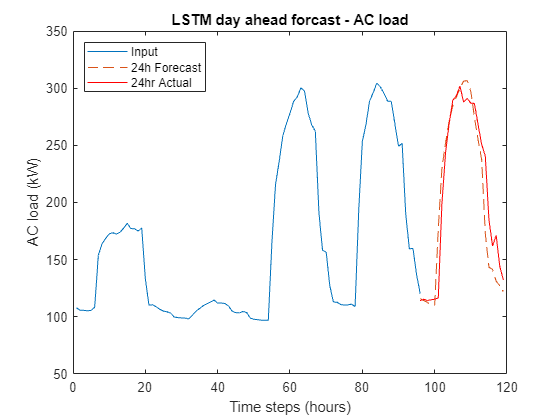

   
   % plot(offset:numTimeSteps,[T(1,offset) Y(1,:)],'--') 
        % plot( offset:numTimeSteps, T(1,offset:numTimeSteps),'r')
   plot(test)
   hold on 
   plot(offset:numTimeSteps, testPreds, '--')
   plot(offset:numTimeSteps, testAct, 'r')
   hold off
   ylabel("AC load (kW)")
   xlabel("Time steps (hours)")
   title("LSTM day ahead forcast - AC load")
   legend("Input","24h Forecast","24hr Actual","Location","northwest")


  testAct = T(1, offset:numTimeSteps)

testAct =   114.0870  115.4010  114.2740  114.8920  115.4270  116.4150  199.0230  243.2800  269.0160  289.3150  293.3540  301.8220  287.7460  291.0200  286.8940  286.6150  268.0800  250.7890  240.6560  185.2090  161.9120  171.4020  144.1020  132.3080


  testPreds = Y(1,:).*sigmaT(1)+meanT(1)

testPreds =   116.0565  114.2153  112.5824  110.1333  110.1021  176.9237  229.5133  251.9604  271.1392  284.4205  292.3153  299.8843  306.1855  306.6492  296.9195  274.6130  254.8456  237.4162  172.9430  143.4943  141.4501  131.2234  127.2467  121.9329


  MAPE =  abs(testAct-testPreds)./(testAct)*100

MAPE =     1.7263    1.0274    1.4803    4.1419    4.6132   51.9767   15.3200    3.5681    0.7893    1.6917    0.3541    0.6420    6.4083    5.3705    3.4945    4.1875    4.9367    5.3323   28.1368   22.5230   12.6377   23.4412   11.6968    7.8416



  meanMAPE = mean(MAPE)

meanMAPE = 9.3057


  intAct = trapz(testAct)

intAct = 4.8698e+03

  intPreds = trapz(testPreds)

intPreds = 4.7652e+03


intMAPE = (abs(intAct - intPreds) / intAct )*100

intMAPE = 2.1494

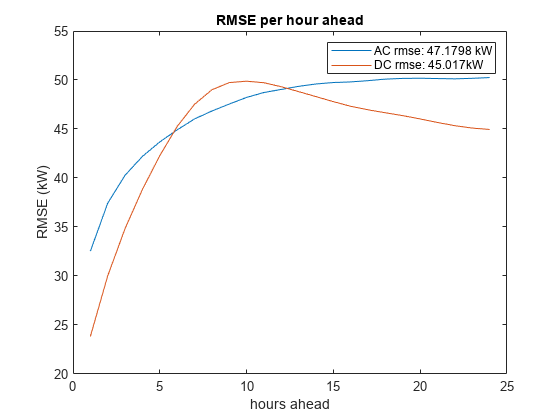

 

        for i = 1:24
        hourlyACrmse(i) = sqrt(mean(rmsePerHr(:,1,i),"all"));
        hourlyDCrmse(i) = sqrt(mean(rmsePerHr(:,3,i),"all"));
        hourlyACmape(i) = mean(mapePerHr(:,1,i),"all");
        hourlyDCmape(i) = mean(mapePerHr(:,3,i),"all");
        end

       figure
        plot(1:24, hourlyACrmse);
        hold on
        plot(1:24,hourlyDCrmse);
        hold off
        legend("AC rmse: "+ sqrt(mean(rmse(:,1)))+" kW", "DC rmse: "+ sqrt(mean(rmse(:,3)))+"kW")
        title("RMSE per hour ahead")
        xlabel("hours ahead")
        ylabel("RMSE (kW)")

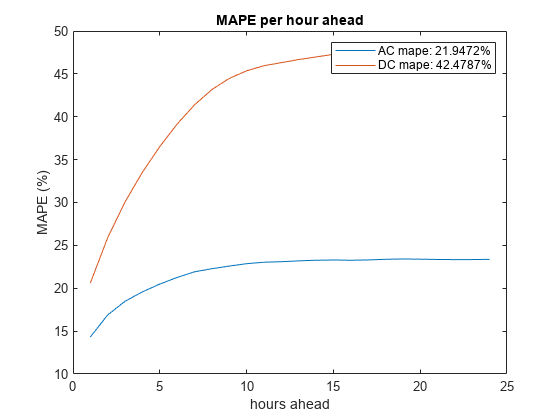

figure
        plot(1:24, hourlyACmape);
        hold on
        plot(1:24,hourlyDCmape);
        hold off
        legend("AC mape: " + mean(hourlyACmape) + "%", "DC mape: "+ mean(hourlyDCmape)+"%")
        title("MAPE per hour ahead")
        xlabel("hours ahead")
        ylabel("MAPE (%)")



        display("AC MAPE: " + mean(mape(:,1))+"%")

    "AC MAPE: 21.9472%"



        display("AC RMSE: " + sqrt(mean(rmse(:,1)))+" kW")

    "AC RMSE: 47.1798 kW"



        display("DC MAPE: " + mean(mape(:,3))+"%")

    "DC MAPE: 42.4787%"



        display("DC RMSE: " + sqrt(mean(rmse(:,3)))+" kW")

    "DC RMSE: 45.017 kW"

